January 4th Noise Removal with Gaussian and speckle

cam = imread("cameraman.tif");

for i = 1:10
    camg(:,:,i) = imnoise(cam,"gaussian");
end

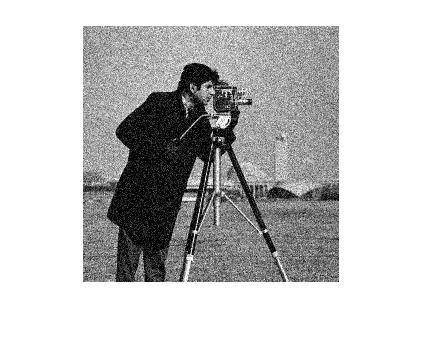

imshow(camg(:,:,2))

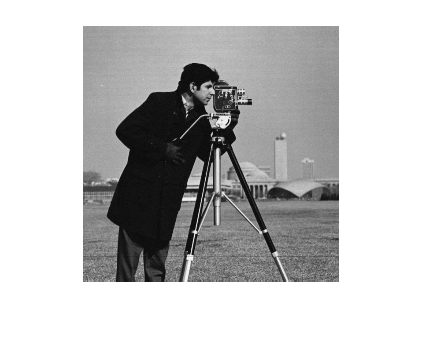


camg_mean = mean(camg,3);

imshow(camg_mean/255);

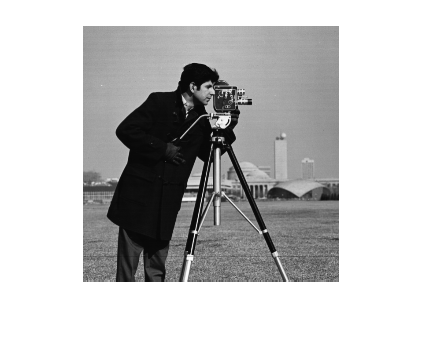

imshow(cam);

periodc noise

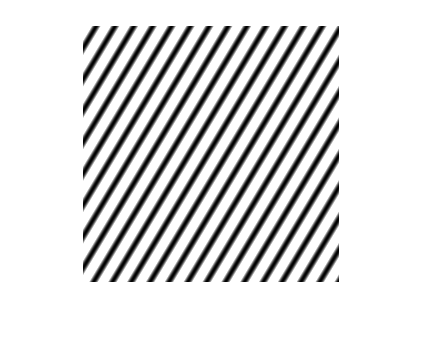

cam = imread("cameraman.tif");

[x,y] = meshgrid(1:256,1:256);

p = sin(x/3+y/5)+1;

imshow(p);

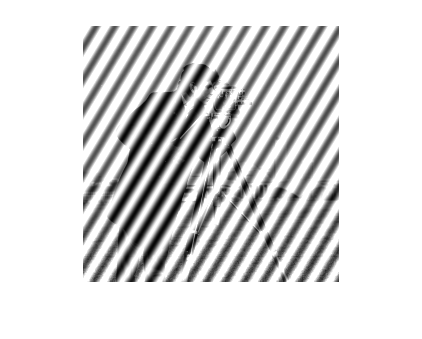


cp = (im2double(cam) + p) / 2;

imshow(cp);

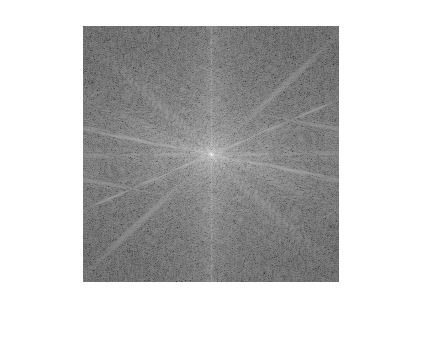

cpf=  fftshift(fft2(cam));
fftshow(cpf,'log');

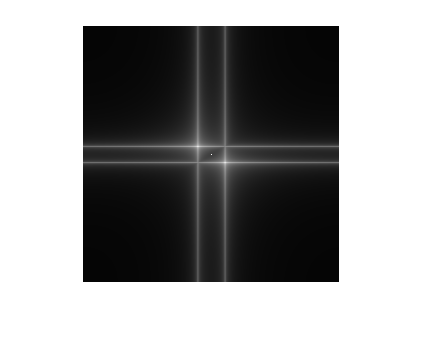


cpf=  fftshift(fft2(p));
fftshow(cpf,'log');

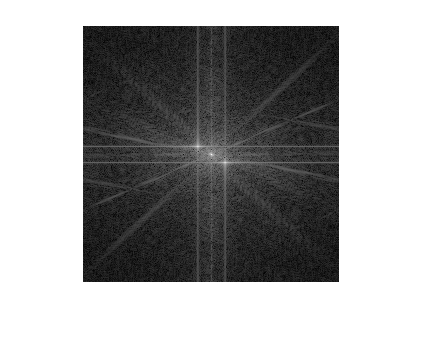


cpf=  fftshift(fft2(cp));
fftshow(cpf,'log');